5)

tic;
subplot(1,3,1);
ahmet = imread('C:\Users\ahmet\Desktop\4.sınıf\image\mp4\ahmet.jpg');
yoldas = imresize(ahmet,0.416);
ahmetGray = rgb2gray(yoldas);
ahmetDoubleGray = im2double(ahmetGray);
 
[row,col] = size(ahmetDoubleGray);
ahmetimfft = fft2(ahmetDoubleGray, row, col); 
ahmetimfft = fftshift(ahmetimfft); 
mask = zeros(size(ahmetimfft));
mask(row/2-row/4 : row/2+row/4, col/2-col/4 : col/2+col/4) = 1; 

 
subplot(1,3,1); imshow(ahmetDoubleGray); 
title('ahmet'); 

ahmetimfft = ahmetimfft .* mask;
subplot(1,3,2); imshow(ahmetimfft); 

title('FFT Image at Frequency Domain'); 

ahmetimfft = ifftshift(ahmetimfft); 
ahmetcompressed = ifft2(ahmetimfft); 
subplot(1,3,3); imshow(ahmetcompressed); 

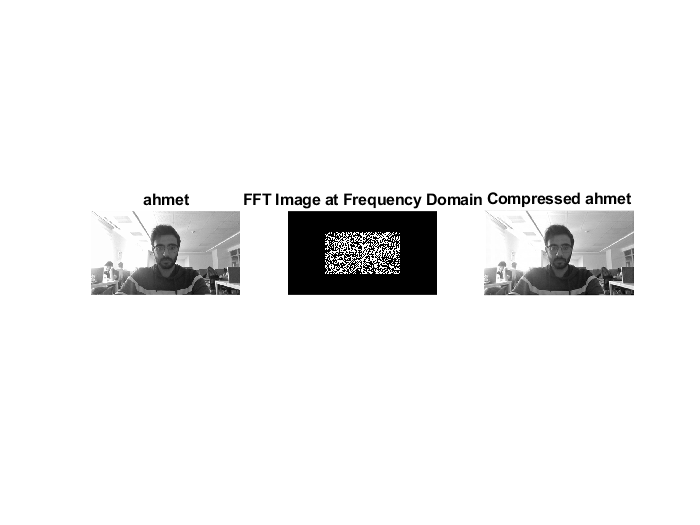

title('Compressed ahmet');

 
whos ahmetDoubleGray;

  Name                   Size               Bytes  Class     Attributes

  ahmetDoubleGray      300x533            1279200  double              



whos ahmetcompressed;

  Name                   Size               Bytes  Class     Attributes

  ahmetcompressed      300x533            2558400  double    complex   



toc;

Elapsed time is 1.220900 seconds.
